# Matlab Basics

**GOLDEN RULE:** use `help functionName `in the command window to have a comprehensive guide on said function.

## BASIC COMMANDS

Scripts are files containing sets of instructions, making it possible to save our work and to comment it.

Comments: all carachters on a line following `%` will not be exectuted. `Ctrl + R / Ctlr + Shift + R` comments / uncomments a line.

With `%%` we begin a new "Section", useful to separate code and keep it tidy and to run code snippets independently.

To clear the workspace:

clear           % frees the workspace from variables
clc             % clears the command window
close all       % closes all open windows (plots, figures, etc.)

`clear` can also be used to clear just specific variables.

Declaring variables:

a = 1           % shows the variable in the command window

a = 1

b = 2;          % doesn't print the value in the command window
a = 2           % variables are overwriteable

a = 2

In the variables we can store scalars (actually considered a 1x1 matrix), vectors (1xn matrix), matrices, strings, etc.

It's not necessary to declare the type of a variable and it is possible to overwrite it.

Matlab is case-sensitive, so the variables `x` and `X` are distinct:

x = 3;
X = 4;
x

x = 3

X

X = 4

Using `who` Matlab lists all the variables currently in the workspace, using `whos` also shows their size, memory allocation and type.

who


Your variables are:

X  a  b  x  



whos

  Name      Size            Bytes  Class     Attributes

  X         1x1                 8  double              
  a         1x1                 8  double              
  b         1x1                 8  double              
  x         1x1                 8  double              



### Predefined variables

Matlab has some built-in variables that do not need to be defined, such as:

exp(1)

ans = 2.7183

i

ans = 0.0000 + 1.0000i

pi

ans = 3.1416

**REMEMBER: **these variables can be overwritten as well, so be careful. In particular, we need to should not use `i` as the index for a cycle, unlike other programming languages.

We can use `format` to change the viewing format of a variable (it doesn't change how it is actually saved or the precision of calculations performed). Use `help format` for a comprehensive list of all possible formats.

format rat
1/7

ans =        1/7     


format default
1/7

ans = 0.1429

`error()` prints an error message and halts the program, `disp()` prints a string in the terminal.

To display a number in the terminal we can either use `disp()` and the `num2str()` commman, or the more versatile `fprintf()` and using the format codes for the various types of variable or action.

 x = 10;
 y = 5.5;
 fprintf('x is %d while y is %f \n' , x, y);

x is 10 while y is 5.500000 


### Elementary mathematical functions

Gin the matrix `A`:

A = magic(3);

We can calculate (for each element):

abs(A);
sqrt(A);
exp(A);
log(A);
log10(A);
log2(A);
sin(A);
cos(A);
tan(A);
asin(A);
acos(A);
atan(A);
sinh(A);
cosh(A);
tanh(A);

## MATRICES AND VECTORS

In Matlab creating ones matrices, zeroes matrices, identity matrices and random matrices is very quick:

clear
a = zeros(3,2)

a =      0     0
     0     0
     0     0


b = ones(4, 3)

b =      1     1     1
     1     1     1
     1     1     1
     1     1     1


c = eye(4)

c =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


d = rand(2, 3)

d =     0.9448    0.4893    0.9001
    0.4909    0.3377    0.3692


To access a value stored in a matrix we need to specify the index it has in the matrix:

**REMEMBER: **Matlab starts counting from 1, unlike many other programming languages.

b(1, 1)

ans = 1

c(1, [1 3])

ans =      1     0


To declare vectors and matrices (commas are not necessary and they don't change row, semicolons change row of the matrix):

clear
a = [1 2 3; 4 5 6; 7 8 9]

a =      1     2     3
     4     5     6
     7     8     9


b = [1, 2, 3]

b =      1     2     3


We can also change row with the `return` key:

c = [1 2 3
    4 5 6
    7 8 9]

c =      1     2     3
     4     5     6
     7     8     9


### Steps

Colons are used to generate vectors with equally spaced values:

clear
a = 1:2:10                  % this means: take numbers from 1 to 10 with steps of 2

a =      1     3     5     7     9


The first number is the starting value, after the semicolon we put the interval between values, the last number is the ending value. If the number between colons is omitted the default step is 1.

A similar way of achieving this is using linearly spaced vecors:

b = linspace(1, 10, 5)      % this means: take 5 equally spaced numbers from 1 to 10

b =     1.0000    3.2500    5.5000    7.7500   10.0000


The first two arguments give the interval, the last number is the number of points to consider (default is 100).

There is a fundamental difference between these two methods: using `linspace `the last number will always be the one selected, using colons the interval will always be the one selected (in the example the two generated vectors are in fact different).

We can use colons to select multiple elements in matrices and vectors:

clear
% a magic matrix is a special matrix, we use it as a quick way to generate pseudo-random matrices
a = magic(5)

a =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


a(2,1:1:3)

ans =     23     5     7


a(2,1:3)

ans =     23     5     7


If we want to select the whole row or column we can just use a colon:

a(1, :)

ans =     17    24     1     8    15


a(:, 1)

ans =     17
    23
     4
    10
    11


If we start from one specific index and want all the row from that onwards we use `end`:

a(1, 2:end)

ans =     24     1     8    15


### Logic states

We get logic states when comparing statements:

clear
logicTrue = 3 < 4

logicTrue = logical
   1


logicFalse = 3 > 4

logicFalse = logical
   0


We can use logic states to filter values in a vector that obey a condition:

a = 1:2:10;
idx = a > 5             % this generates a vector of logic 0s and 1s

idx = 1×5 logical array
   0   0   0   1   1


a(idx)                  % this generates a vector containing only the values that obey the condition

ans =      7     9


If we compare matrices Matlab compares them element by element.

A = ones (3);
B = 2*A;
B > A

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


To check if two generic elements (scalars, vector, matrices) are equal we can use the `isequal()` command:

isequal(A, B)

ans = logical
   0


isequal(A,A)

ans = logical
   1


B(1,1) = 1;
B ~= A

ans = 3×3 logical array
   0   1   1
   1   1   1
   1   1   1


## OPERATIONS WITH MATRICES

clear

Basic matrix operations such as sum and row-column product have basic syntax:

a = [1 2 3; 4 5 6; 7 8 9];
b = [1 0 1; 2 0 2; 3 0 3];
a + b

ans =      2     2     4
     6     5     8
    10     8    12


a * b

ans =     14     0    14
    32     0    32
    50     0    50


3 * a

ans =      3     6     9
    12    15    18
    21    24    27


3 + a

ans =      4     5     6
     7     8     9
    10    11    12


To transpose vectors and matrices we use an apostrophe:

c = [1 2 3]'

c =      1
     2
     3


Matrix multiplication is subject to linear algebra rules, and we can multuply two matrices only if their dimensions are compatible (mxp * pxn):

a * c               % if c hadn't been transposed this would have given an error

ans =     14
    32
    50


To calculate element-by-element operations we add a `.` before the operator:

a .* b

ans =      1     0     3
     8     0    12
    21     0    27


a ./ b

ans =     1.0000       Inf    3.0000
    2.0000       Inf    3.0000
    2.3333       Inf    3.0000


a .^ 2              % different from a^2 = a*a

ans =      1     4     9
    16    25    36
    49    64    81


While it isn't mathematically correct, we can add a vector to a matrix. Matlab duplicates the vector and sums it to every row or column of the matrix.

a + c

ans =      2     3     4
     6     7     8
    10    11    12


a + c'

ans =      2     4     6
     5     7     9
     8    10    12


`cross` calculates the cross product between two 3x3 vectors:

d = [4 5 6];
cross(c,d)

ans =     -3     6    -3


`max()` returns the largest element of a vector and a row vector with the largest element of each column of a matrix. The exact opposite happens with `min()`:

max(a)

ans =      7     8     9


min(c)

ans = 1

To extract the main diagonal of a matrix as a column vector we use `diag()`:

diag(a)

ans =      1
     5
     9


Using an argument `k` after the matrix it extracts the over- or under-diagonal of order `k` (`k` must be between `-n+1` and `n-1`):

diag(a,1)

ans =      2
     6


Using `diag()` on a vector creates a square matrix with the elements from the vector on the main diagonal (using the argument `k` moves them on the over- or under-diagonal of order `k`):

diag(c, 1)

ans =      0     1     0     0
     0     0     2     0
     0     0     0     3
     0     0     0     0


Using `tril()` (or `triu()`) on a matrix we create an upper (or lower) triangle matrix with the elements from the original matrix.

tril(a)

ans =      1     0     0
     4     5     0
     7     8     9


The `norm()` function returns the 2-norm (Euclidean) of a vector:

norm(c)

ans = 3.7417

Using an argument `n` after the vector we calculate the `n`-norm of that vector, defined as $||v||_n = (\sum_{i=1}^{length(v)}|v_i|^n)^\frac{1}{n}$:

norm(c, 3)

ans = 3.3019

Using `inf` as an argument we calculate the infinite norm of the vector, defined as $||v||_\infty = \max_{1 \leq i \leq length(v)} |v_i|$:

norm(c, inf)

ans = 3

### Useful functions

`size()` returns a vector with the number of rows and columns (if it is a 3-D array it also contains the number of pages).

size(a)

ans =      3     3


size(c')

ans =      1     3


For a vector we use` lenght()`:

length(c)

ans = 3

`sum() `sums all elements of a vector:

sum(c)

ans = 6

If the argument is a matrix it returns a row vector containing the sum of all the elements on the corresponding column:

sum(a)

ans =     12    15    18


If we want the sum of all values in a matrix:

sum(sum(a))

ans = 45

sum(a(:))

ans = 45

`cumsum()` does the cumulative sum of all the elements with the ones from previous rows:

cumsum(a)

ans =      1     2     3
     5     7     9
    12    15    18


`cumprod()` does the cumulative product of all the elemens with the previous ones on the same row:

cumprod(a)

ans =      1     2     3
     4    10    18
    28    80   162


An important function is `diff()`, that calculates the difference between each element and the corresponding element on the previous row (the output has the row dimension reduced by 1):

diff(a)

ans =      3     3     3
     3     3     3


`cumsum()`, `cumprod()`, `diff()` can be used also with vectors. In this caase they calculate sum, product and difference with the previous element(s):

v = 1:1:10;
cumsum(v)

ans =      1     3     6    10    15    21    28    36    45    55


cumprod(v)

ans =            1           2           6          24         120         720        5040       40320      362880     3628800


diff(v)             % the size is reduced by 1

ans =      1     1     1     1     1     1     1     1     1


`eig()` calculates eigenvalues for the matrix in the argument:

eig(a)

ans =    16.1168
   -1.1168
   -0.0000


## FOR AND WHILE LOOPS

clear
a = [1 2 3; 4 5 6; 7 8 9];

Loops work in the same way as in other programming languages. The following example uses a for loop to separate a matrix in row vectors:

for k = 1:3             % it's good practice not to use i as it represents the imaginary unit
    a(k,:)
end

ans =      1     2     3


ans =      4     5     6


ans =      7     8     9


It is also possible to iterate on the elements of a vector:

N = 2:2:10;
for n = N
    n
end

n = 2

n = 4

n = 6

n = 8

n = 10

The while loop uses logic statements to determine when to exit the cycle.

a = 0

a = 0

while a < 4
    disp('Not yet')
    a = a + 1;
end

Not yet
Not yet
Not yet
Not yet


It is possible to use the `for` cycle on matrices, it iterates on each column vector (or on vectors, iterating on scalars):

for i = magic(5)
    i
end

i = 5×1
    17
    23
     4
    10
    11


i = 5×1
    24
     5
     6
    12
    18


i = 5×1
     1
     7
    13
    19
    25


i = 5×1
     8
    14
    20
    21
     2


i = 5×1
    15
    16
    22
     3
     9


## IF-ELSE STATEMENTS AND SWITCH

Just like the loops, `if-else` statements work in the same way as in other programming languages. The following example prints a different results based on the different case:

v = [1 2 3];
var = randsample(v,1);          % randsample(v,k) returns k random samples from the vector v
if var == 1
    disp('One')
elseif var == 2
    disp('Two')
else
    disp('Three')
end

One


If there are many different cases it's more convenient to use `switch`:

switch var
    case 1
        disp('One')
    case 2
        disp('Two')
    otherwise
        disp('Three')
end

One


The "different" operator in not `!=` but `~=.`

The "and", "or" and "not" logic operators are used as always.

clear
a = 1;
b = 1;

if a && b
    disp('true')
end

true


## FUNCTION HANDLES

clear

In case we have a simple function we use a function handle to define "inline" a series of mathematical operations in a certain variable that will later be calculated assigning a value to that variable:

f = @(x) x^2 + 3*x + 1;
f(2)

ans = 11

This also works with matrices, if we define element-by-element operations (a fast way to calculate the same operation for different values):

fmat = @(x) x.^2 + 3.*x + 1;
fmat(1:8)

ans = 1×8
     5    11    19    29    41    55    71    89


It is possible to evaluate functions with more than one variable:

fmulti = @(x,y) x.^3+y.^3

fmulti = function_handle with value:
    @(x,y)x.^3+y.^3


fmulti(2,4)

ans = 72

We could also use `eval()` or `inline()`, but function handles are equivalent (if not more flexible), so we just review this one method.

## FUNCTIONS

Functions are a way to use multiple times the same piece of code, as well as a tool to help making code more structured and readable. Functions work on diferent workspaces and don't share variables in either way with the main worskpace.

A simple function might be a sum between inputs:

function output = functionName(input1, input2)
    output = input1 + input2;
end

It's possible to call a function later in the code using the following syntax:

in1 = 1;
in2 = 2;
result = functionName(in1, in2)

result = 3

To make code more readable long functions are often put in a different `.m` file, also in order to make them usable in different scripts. The file name MUST be the same name given to the function. It is always a good call to insert a few lines describing the function using a comment right after the definition. This comment will show up when we type `help functionName` in the terminal.

Functions may behave differently depending on the number of input arguments (obtainable using the fommand `nargin`) or output arguments that are required (obtainable using the fommand `nargout`).

Functions can be nested, and can have multiple outputs. In case of nested functions they share workspaces:

[result1, result2, result3] = secondFunction(1, 2)

result1 = 3

result2 = -1

result3 = 4

function [output1, output2, output3] = secondFunction(input1, input2)
    output1 = input1 + input2;
    output2 = input1 - input2;
    output3 = nestedFunction(output1, output2);
    % in this case it's not really necessary to declare them since they share workspaces
    function uscita = nestedFunction(output1, output2)
        uscita = output1 - output2;
    end
end

If we want only tthe first output argument of a function we can ask for a scalar and not a vector. If we want the *nth* output we put `~` *n-1 *times before the output we want in a vector.

result1 = secondFunction(1, 2)

result1 = 3

[~, result2] = secondFunction(1, 2)

result2 = -1

It is possible to create "void" functions (with no output) or without any input.

To share the value of variables it is also possible to declare them as `global`.

### Example: derivative using `diff()`

clear

f = @(x) x.^2 + 3.*x + 1;           % generic function

result = derivative(f, 2)

result = 7

function df = derivative(f, x0)
    % this is a mathematical "trick" to have a small but finite change
    epsilon = max(abs(x0)*sqrt(eps), sqrt(eps));        % eps is the smallest finite value Matlab can interpret
    df = (f(x0+epsilon)-f(x0))/epsilon;
end

Which is the discretization of:


$$\lim_{h \to 0} \frac{f(x_0+h)-f(x_0)}{h} \triangleq f'(x_0)$$


## PLOTS

Plots are fundamental in visualizing data. They plot by points, linking element by element two vectors.

A LOT of different options can be tweaked, refer to `help plot` to get to know all of them.

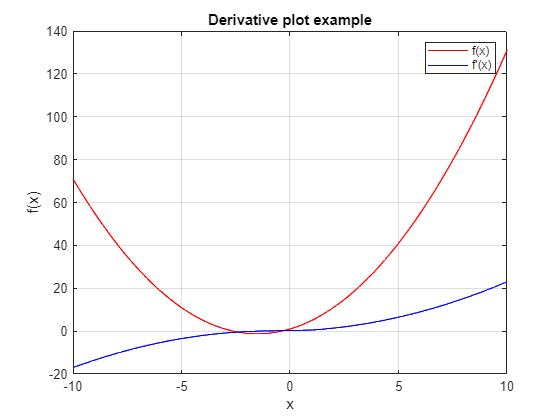

x = -10:0.1:10;
y = f(x);
dy = derivative(f, x');      % x must be transposed in order to get the correct operation in the function
plot(x, y, "r")
grid on
xlabel('x');
ylabel('f(x)');
title('Derivative plot example');
hold on
plot(x, dy(:, 1), "b")           % dy is actually a matrix, we need just the first column
legend('f(x)',"f'(x)")
hold off

It is also possible to create 3D plots using the `plot3` command.

To create plots with lograitmic scales we use `semilogx`, `semilogy` or `loglog`:

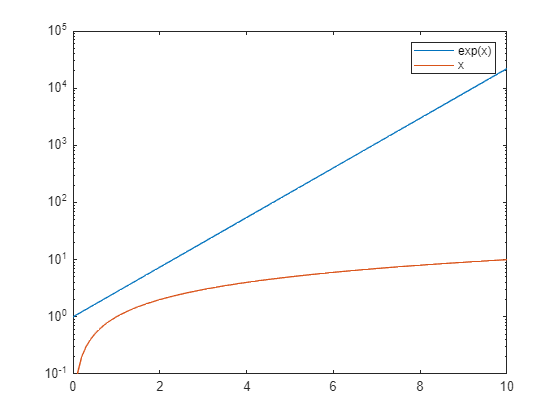

v = 0:0.1:10;
semilogy(v,exp(v), v,v)
legend("exp(x)","x")

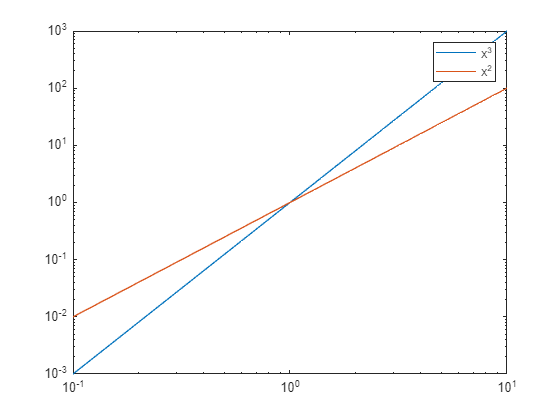

loglog(v,v.^3, v,v.^2)
legend("x^3", "x^2")

## STRUCTS

Structs are used as a way to neatly categorize variables. We declare a struct giving it a name, and then creating and accessing its fields using a dot.

**BE CAREFUL:** rerunning this section will give an error here, we later vectorized this structure, so Matlab wants an index.

exampleRocket.name = 'orion';
exampleRocket.thrust.test1 = 2:3:20;
exampleRocket.thrust.test2 = 3:2:20;
exampleRocket.thrust.test1(:)

ans = 7×1
     2
     5
     8
    11
    14
    17
    20


It is possible to generate vectors of structs.

exampleRocket(2).name = 'crater';                   % small easter egg ;)

Function handles can be saved inside structs.

f = @(x) x.^2 + 3.*x + 1;
exampleStruct.function = f;
result = derivative(exampleStruct.function, 2)

result = 7

Everything said so far can be extended to structs.

### Example:

car.position = 0:5:100;
car.timestamps = 1:21;
car.speed = calculate_spd(car)

car = struct with fields:
      position: [0 5 10 15 20 25 30 35 40 45 50 55 60 65 70 75 80 85 90 95 100]
    timestamps: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21]
         speed: [0 2.5000 3.3333 3.7500 4 4.1667 4.2857 4.3750 4.4444 4.5000 4.5455 4.5833 4.6154 4.6429 4.6667 4.6875 4.7059 4.7222 4.7368 4.7500 4.7619]


function spd = calculate_spd(car)
    pos = car.position;
    t = car.timestamps;
    spd = pos./t;
end

## EXERCISE: NEWTON'S METHOD

Implement Newton's method to calculate the root of a function.

For a real valued function, we follow this iterative algorithm:


$$x_{n+1} = x_n - \frac{f(x_n)}{f'(x_n)}$$


clear
clc

f = @(x) sin(x)-cos(x/2)+0.5;
df = @(x) cos(x)+0.5*sin(x/2);          % this derivative was calculated by hand
x0 = 0;                                 % initial estimation of the zero (a wild guess)
tol = 1e-5;                             % tol defines the tolerance

x_zero = newton(f, df, x0, tol)

x_zero = 0.4895

function x_zero = newton(f, df, x0, tol)
    x_zero = x0;                                    % initializing the zero
    while abs(f(x_zero)) > tol                      % until the zero we found isn't within the tolerance
        x_zero = x_zero - f(x_zero)/df(x_zero);     % the actual new estimation
    end
end

Checking the result with the built-in function:

fzero(f,[0 1])

ans = 0.4895